ZAD. 1

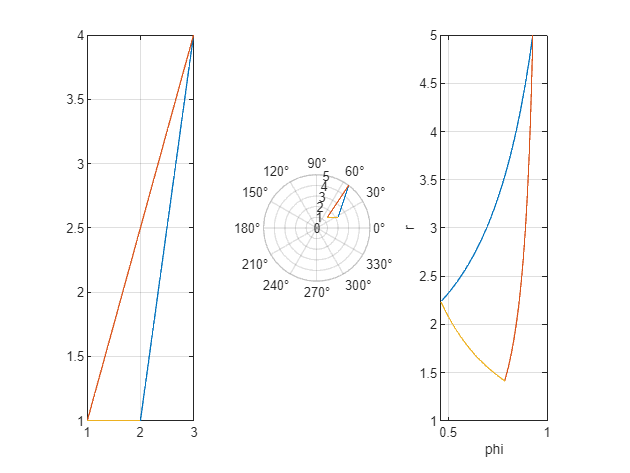

clear;
P1 = [2, 1]; P2 = [3, 4]; P3 = [1, 1];
cart2pol_visualize(P1, P2, P3);

ZAD. 2

% zad2
clear;
x0 = 0.5;  % m
x0_poch = 0;  % m/s
m = 1;  % kg
k = 0.5;  % N/m
a = 0.01;  % N/m^3
u = 0;

% zad3
global K alfa beta
w0 = 0;
alfa = 0.5;
beta = 1;
K = 0.5;

best_x = fmincon(@ident_error, [K, alfa, beta], [], [], [], [], [0 0 0], [])


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


best_x =     1.3266    0.0053    1.6873


function error = ident_error(x)
    global K alfa beta

    K = x(1);
    alfa = x(2);
    beta = x(3);
    
    sim_out = sim("zad2_system.slx");
    
    error = double(sim_out.error.signals.values(end));
end

function [r1, phi1, r2, phi2, r3, phi3] = cart2pol_visualize(P1, P2, P3)
    x1 = P1(1); y1 = P1(2);
    x2 = P2(1); y2 = P2(2);
    x3 = P3(1); y3 = P3(2);

    a1 = (y1 - y2) / (x1 - x2);
    a2 = (y2 - y3) / (x2 - x3);
    a3 = (y3 - y1) / (x3 - x1);

    b1 = y1 - a1 * x1;
    b2 = y2 - a2 * x2;
    b3 = y3 - a3 * x3;

    l1 = @(x) a1 * x + b1;
    l2 = @(x) a2 * x + b2;
    l3 = @(x) a3 * x + b3;
    
    n = 100;

    v_x1 = linspace(x1, x2, n);
    v_x2 = linspace(x2, x3, n);
    v_x3 = linspace(x3, x1, n);

    figure;
    subplot(1, 3, 1)
    plot(v_x1, l1(v_x1), v_x2, l2(v_x2), v_x3, l3(v_x3));
    grid on;

    subplot(1, 3, 2)
    [phi1, r1] = cart2pol(v_x1, l1(v_x1));
    [phi2, r2] = cart2pol(v_x2, l2(v_x2));
    [phi3, r3] = cart2pol(v_x3, l3(v_x3));
    polarplot(phi1, r1, phi2, r2, phi3, r3);
    grid on;
    
    subplot(1, 3, 3)
    plot(phi1, r1, phi2, r2, phi3, r3);
    xlabel("phi");
    ylabel("r");
    grid on;
end